clearvars;

### Initial parameter

f = 440; % Hz
c = 343; % m/s
k = 2*pi*f/c; % Wave number

## Spherical Harmonics

The purpose of this script is to research how an input pressure can be represented in spherical harmonics and how a spherical harmonics representation can be translated to an output pressure.

### Spherical Harmonics - Sound pressure

The sound pressure at a point $x\{r,\theta,\phi\}$ with respect to the origin can be expressed as


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where

$C_{lm}(k)$ are the spherical harmonics coefficients,

$k=\frac{2\pi f}{c}$ is the wave number,

$f$ is the frequency,

$c$  is the speed of sound propagation

$j_l(kr)$ is the $l$th order Bessel function of the first kind,

$Y_{lm}(\theta,\phi)$ are the spherical harmonics.

#### Bessel function

l = 1, m = 1; r = 1; % Meaningless values for degree, order, radius

l = 1

J = besselj(l,k*r);

#### Spherical harmonics

The spherical harmonic of degree $l$ and order $m$ is given by


$$Y_{lm}(\theta,\phi) \equiv (-1)^m \sqrt{\frac{2l+1}{4\pi}\frac{(l-m)!}{(l+m)!}}P_l^m(\cos(\theta))e^{im\phi}$$


where 

$P_n^m(x)$ is the associated Legendre function, unnormalized.

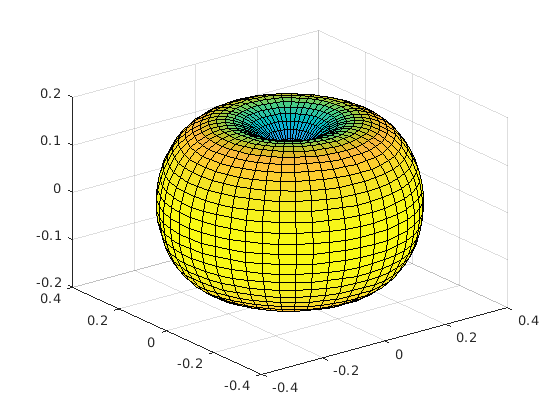

% create a 2D grid
th = linspace(0,pi,50);    % inclination
phi = linspace(0,2*pi,50); % azimuth
[th,phi] = meshgrid(th,phi);

% compute spherical harmonic of degree 3 and order 1
Y = harmonicY(l,m,th,phi);

% plot the magnitude
[x,y,z] = sph2cart(phi,pi/2-th,abs(Y));
surf(x,y,z,abs(Y));

### Approximation

The sound field can be approximated by


$$P(r,\theta,\phi,k) = \sum_{l=0}^L \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where


$$L = \lceil \frac{ekr}{2} \rceil$$


$e$ is the natural exponential

### Sound pressure - Harmonic Coefficients

We have 


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


By multiplying both side by $\overline\mathbf{Y}_{lm}$ and integrating over the sphere we get:


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


where 

$\overline\mathbf{Y}_{lm}$ is the complex conjugate matrix of $\mathbf{Y}_{lm}$

#### Plane wave expansion


$$e^{i\mathbf k \cdot \mathbf r} = \sum_{l=0}^\infty (2l+1)i^lj_l(kr)P_l(\hat \mathbf k \cdot \hat \mathbf r)$$
    

where

$i$ is the imaginary unit,

$\mathbf k$ is a wave vector of length $k$,

$\mathbf r$ is a position vector of length $r$,

$\mathbf \hat k = \frac{\mathbf k}{|\mathbf k|}$ and $\mathbf \hat r$ is the unit vector of $\mathbf k$ and $\mathbf r$ respectively.

$P_l$ is the Legendre polynomials.

clearvars;
f = 1000; c = 343; kx = 2*pi*f/c; rx = 1;
k = [kx;0;0]; r = [rx;0;0];
L = 100;
wave = exp(1i*dot(k,r))

wave = 0.8622 - 0.5066i

wave_exp = 0;
for l = 0:L
    wave_exp = wave_exp + (2*l+1)*i^l*sphbessel(l,kx*rx)*legendreP(l,1);
end
wave_exp

wave_exp = 0.8622 - 0.5066i

#### Plane wave - Expansion in Spherical Harmonics

According to [https://en.wikipedia.org/wiki/Plane-wave_expansion](https://en.wikipedia.org/wiki/Plane-wave_expansion) as plane wave can be expressed as a linear combination of spherical harmonics:


$$e^{i\mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(kr)Y_{lm}(\mathbf \hat k)\overline{Y}_{lm}(\mathbf \hat r),$$


in spherical coordinates  $\mathbf k\{\rho_k,\theta_k,\phi_k\}$ and  $\mathbf r\{\rho_r,\theta_r,\phi_r\}$.


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k,\rho_k)\overline{Y}_{lm}(\theta_r,\phi_r,\rho_r),$$


where 


$$\mathbf k \cdot \mathbf r = \rho_k\rho_r[\sin\theta_k\sin\theta_r\cos(\phi_k-\phi_2)+\cos\theta_k\cos\theta_r]$$


$\rho_k = \frac{2\pi}{\lambda} = \frac{2\pi f}{c}$,

$\lambda$ is the wave length.

clearvars;
f = 300; c = 343;
rho_r = 0.01:0.01:10; r = [zeros(1,length(rho_r));rho_r;zeros(1,length(rho_r))];
k = [0;2*pi*f/c;0]; rho_k = norm(k);
the_k = atan(k(2)/k(1)); phi_k = atan((k(1)^2+k(2)^2)/k(3));
the_r = max(atan(r(2,:)./r(1,:))); phi_r = max(atan((r(1,:).^2+r(2,:).^2)./r(3,:)));
nr = length(rho_r);

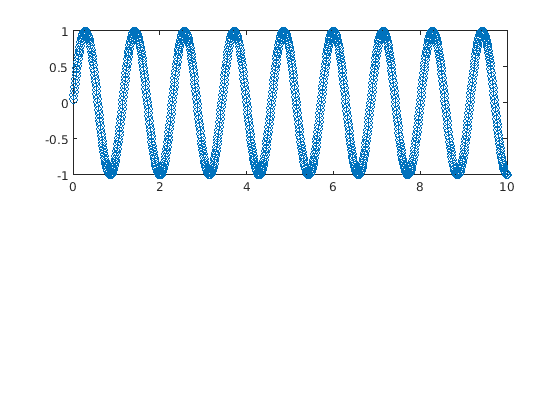

wave = exp(1i*myDot(k,r));
figure;
subplot(211)
plot(rho_r, imag(wave),'-o');

Harmonics Matrix

L = max(ceil((exp(1)*rho_k*rho_r/2)));
Yk = zeros(L+1,2*L+1);
Yr = Yk;
for l=0:L
    idxl = l+1;
    for m=-l:l
        idxm = m+idxl;
        Yk(idxl,idxm) = harmonicY(l,m,the_k,phi_k,1);
        Yr(idxl,idxm) = harmonicY(l,m,the_r,phi_r,1);
    end
end
cYr = conj(Yr);

Precalculate Summation Matrix in vectorized form.

l = 0:L; m = -L:L;
idxl = l+1; idxm = m+L+1;
nr = length(rho_r);
PP = zeros(length(l),length(m),nr);
for n=1:nr
    PP(:,:,n) = (1i.^(l+2)').*sphbessel(l',rho_k*rho_r(n)).*Yk(idxl,idxm,1).*cYr(idxl,idxm,1);
end

Why in this calculation we need $i^{l+2}$ is not quite clear...

l

l =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


vi = i.^l

vi =    1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i


vi = i.^(l+2)

vi =   -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   0.0000 - 1.0000i


Computing wave using spherical harmonics expansion

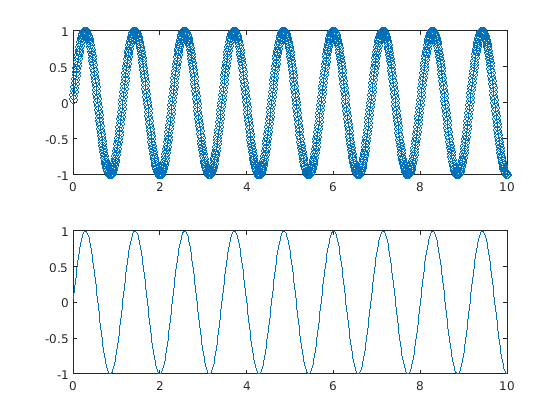

P = zeros(1,nr);
for n=1:nr
    for l=0:L
        idxl = l+1;
        for m=-l:l
            idxm = m+idxl;
            P(n) = P(n) + PP(idxl,idxm,n);
        end
    end
    
end
P = 4*pi*P;
subplot(212);
plot(rho_r,imag(P));

Computing wave with spherical harmonics using a loop. Slower...

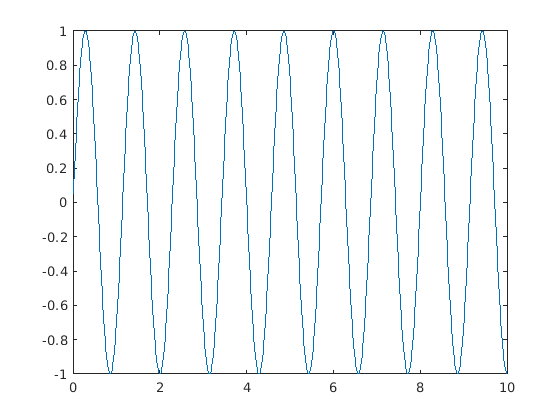

P = zeros(1,nr);
h = waitbar(0,"initializing");
L = max(ceil((exp(1)*rho_k*rho_r/2)));
for n=1:nr
    for l=0:L
        idxl = l+1;
        for m=-l:l
            idxm = m+idxl;
            P(n) = P(n) + 1i^l*sphbessel(l,rho_k*rho_r(n))*Yk(idxl,idxm,1)*cYr(idxl,idxm,1);
        end
    end
    P(n) = P(n) * 4 * pi;
    waitbar(n/nr,h,"loading");  
end
close(h);
figure;
plot(rho_r,imag(P));

### Function deklaration

function y = myDot(k,r)
    y = k(1).*r(1,:) + k(2).*r(2,:) + k(3).*r(3,:);
end